# Charging Events Distribution Fitting for Levels 1&2

By: Dr. A. Balgobin

### Level 1 Data

#### Starting Times

opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:D215500";

% Specify column names and types
opts.VariableNames = ["timeBegin", "durations", "Var3", "DateAndTime"];
opts.SelectedVariableNames = ["timeBegin", "durations", "DateAndTime"];
opts.VariableTypes = ["datetime", "double", "char", "datetime"];

% Specify variable properties
opts = setvaropts(opts, "Var3", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var3", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "timeBegin", "InputFormat", "");
opts = setvaropts(opts, "DateAndTime", "InputFormat", "");

% Import the data
level1cleanedAB = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\level1_cleaned_AB.xlsx", opts, "UseExcel", false); 
clear opts
level1cleanedAB(1,:) = []

level1cleanedAB = 215499×3 table
         timeBegin          durations        DateAndTime     
    ____________________    _________    ____________________

    01-Jan-2010 11:30:00    0.076389     01-Jan-2010 11:30:00
    02-Jan-2010 11:30:00    0.020833     02-Jan-2010 11:30:00
    05-Jan-2010 16:40:00    0.055556     05-Jan-2010 16:40:00
    05-Jan-2010 20:20:00    0.027778     05-Jan-2010 20:20:00
    06-Jan-2010 20:10:00    0.027778     06-Jan-2010 20:10:00
    08-Jan-2010 13:30:00    0.034722     08-Jan-2010 13:30:00
    09-Jan-2010 18:30:00    0.027778     09-Jan-2010 18:30:00
    10-Jan-2010 10:50:00    0.020833     10-Jan-2010 10:50:00
    10-Jan-2010 12:30:00    0.041667     10-Jan-2010 12:30:00
    10-Jan-2010 18:50:00    0.083333     10-Jan-2010 18:50:00
    12-Jan-2010 01:40:00    0.034722     12-Jan-2010 01:40:00
    12-Jan-2010 11:00:00    0.034722     12-Jan-2010 11:00

L1_start_times_tstamps = timeofday(level1cleanedAB.timeBegin); %HH:MM:SS format of data
L1_start_times_mins = minutes(timeofday(level1cleanedAB.timeBegin)) %Start time converted to minutes(total), eg. 11:30 PM To 690 mins

L1_start_times_mins =          690
         690
        1000
        1220
        1210
         810
        1110
         650
         750
        1130


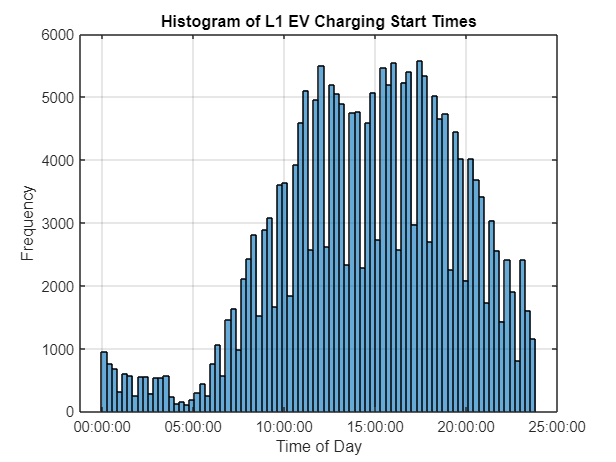

figure;
histogram(L1_start_times_tstamps)
grid on
title("Histogram of L1 EV Charging Start Times")
xlabel("Time of Day")
ylabel("Frequency")

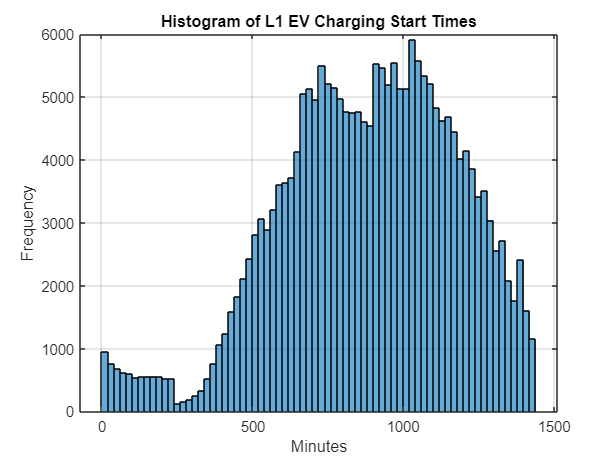

figure;
histogram(L1_start_times_mins)
grid on
title("Histogram of L1 EV Charging Start Times")
xlabel("Minutes")
ylabel("Frequency")

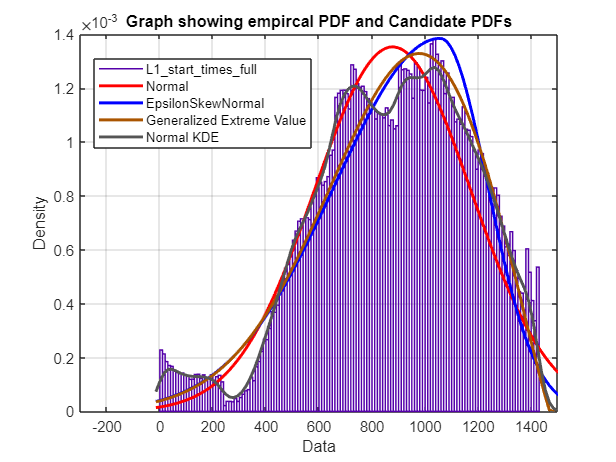

%fitting distributions
L1_start_times_mins = L1_start_times_mins(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "L1_start_times_full"
[CdfF,CdfX] = ecdf(L1_start_times_mins,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(L1_start_times_mins,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'L1_start_times_full';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "Normal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('normal',[ 877.4973897791, 294.9040628467])
pd1 = fitdist(L1_start_times_mins, 'normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal';

% --- Create fit "EpsilonSkewNormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('EpsilonSkewNormal',[ 1058.312782197, 288.1665641384, 0.3834142032451])
pd2 = fitdist(L1_start_times_mins, 'EpsilonSkewNormal');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'EpsilonSkewNormal';

% --- Create fit "Generalized Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('generalized extreme value',[ -0.4742377799731, 317.403479637, 801.4172906818])
pd3 = fitdist(L1_start_times_mins, 'generalized extreme value');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Generalized Extreme Value';

% --- Create fit "Normal KDE"
pd4 = fitdist(L1_start_times_mins,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.333333 0.333333 0.333333],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

legend("Position",[0.15417,0.68175,0.35179,0.19286])

xlim([-300 1500])
ylim([0.00000 0.00140])
zlim([-1.00 1.00])
grid on
title("Graph showing empircal PDF and Candidate PDFs for Level 1 Starting Times")

#### Truncating Starting Times

L1_start_times_mins_truncated = L1_start_times_mins(L1_start_times_mins > 300)

L1_start_times_mins_truncated =          690
         690
        1000
        1220
        1210
         810
        1110
         650
         750
        1130


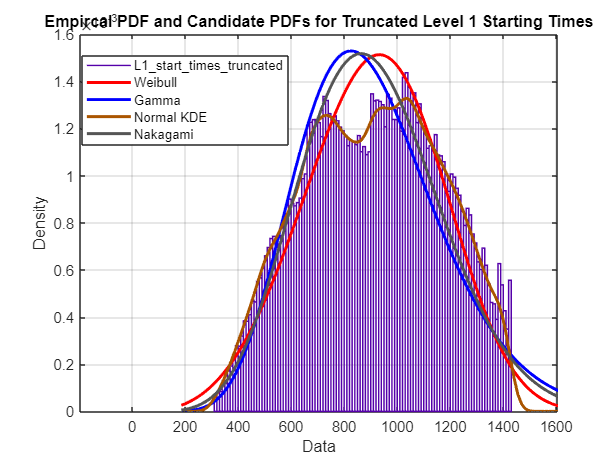

L1_start_times_mins_truncated = L1_start_times_mins_truncated(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "L1_start_times_truncated"
[CdfF,CdfX] = ecdf(L1_start_times_mins_truncated,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(L1_start_times_mins_truncated,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'L1_start_times_truncated';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "Weibull"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('weibull',[ 1002.732063415, 3.983740371951])
pd1 = fitdist(L1_start_times_mins_truncated, 'weibull');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Weibull';

% --- Create fit "Gamma"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('gamma',[ 11.1806613302, 81.11180386072])
pd2 = fitdist(L1_start_times_mins_truncated, 'gamma');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Gamma';

% --- Create fit "Normal KDE"
pd3 = fitdist(L1_start_times_mins_truncated,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% --- Create fit "Nakagami"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd4 = ProbDistUnivParam('nakagami',[ 3.117062787616, 889269.6717914])
pd4 = fitdist(L1_start_times_mins_truncated, 'nakagami');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.333333 0.333333 0.333333],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Nakagami';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
grid on
xlim([-195 1605]);
ylim([0.00000 0.00160]);
legend("Position",[0.13452,0.68889,0.33393,0.19286]);
title("Empircal PDF and Candidate PDFs for Truncated Level 1 Starting Times");

#### Durations

opts = delimitedTextImportOptions("NumVariables", 1);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = "durations";
opts.VariableTypes = "double";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
l1durationsxformed = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\l1_durations_xformed.csv", opts)

l1durationsxformed = 215499×1 table
    durations
    _________

       110   
        30   
        80   
        40   
        40   
        50   
        40   
        30   
        60   
       120   
        50   
        50   
        50   
        70   
        90   
        40   


clear opts

%%Durations
l1_durs = l1durationsxformed.durations

l1_durs =    110
    30
    80
    40
    40
    50
    40
    30
    60
   120


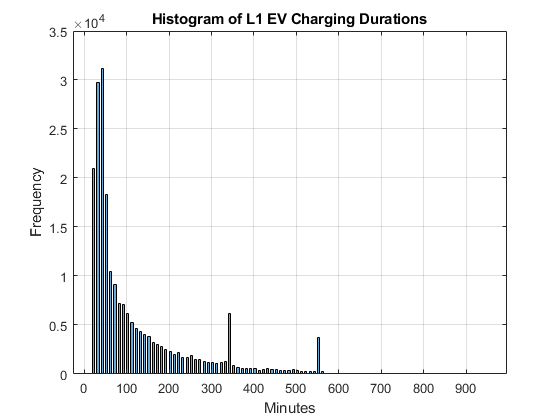

figure;
histogram(l1_durs)
grid on
title("Histogram of L1 EV Charging Durations")
xlabel("Minutes")
ylabel("Frequency")

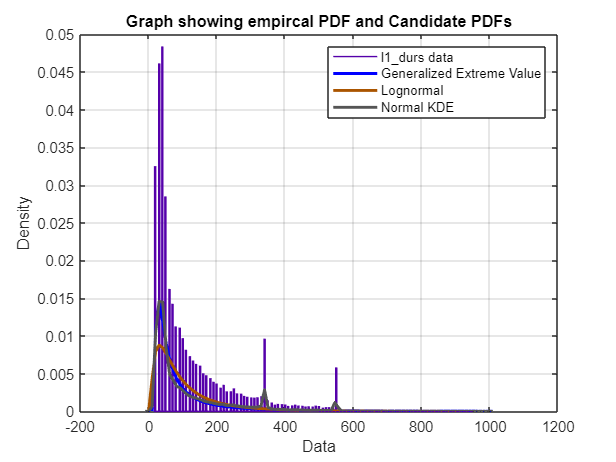

l1_durs = l1_durs(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "l1_durs data"
[CdfF,CdfX] = ecdf(l1_durs,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(l1_durs,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'l1_durs data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "fit 1"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('half normal',[ 20, 158.6975553786])
pd1 = fitdist(l1_durs, 'half normal');
% This fit does not appear on the plot

% --- Create fit "Generalized Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('generalized extreme value',[ 0.9168580214909, 34.52724327982, 45.74060763155])
pd2 = fitdist(l1_durs, 'generalized extreme value');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Generalized Extreme Value';

% --- Create fit "Lognormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('lognormal',[ 4.319426174934, 0.9266586052789])
pd3 = fitdist(l1_durs, 'lognormal');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Lognormal';

% --- Create fit "Normal KDE"
pd4 = fitdist(l1_durs,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.333333 0.333333 0.333333],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% Adjust figure
box on;
grid on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
grid on
title("Graph showing empircal PDF and Candidate PDFs")

#### Truncated Durations

L1_durations_trunc = l1_durs(l1_durs < 320 );
L1_durations_trunc = L1_durations_trunc(L1_durations_trunc > 40 );

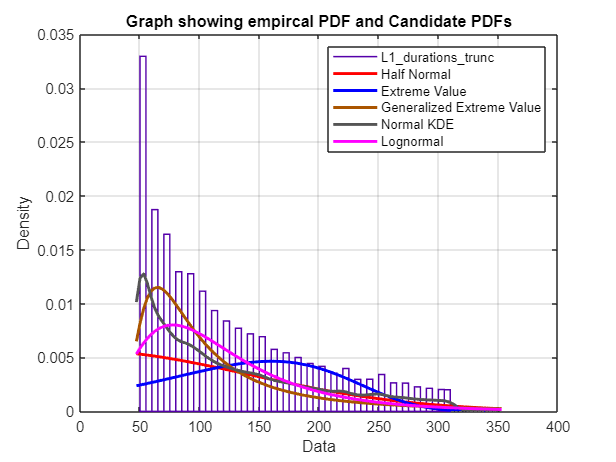

L1_durations_trunc = L1_durations_trunc(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "L1_durations_trunc"
[CdfF,CdfX] = ecdf(L1_durations_trunc,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(L1_durations_trunc,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'L1_durations_trunc';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "Half Normal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('half normal',[ 40, 108.1879726153])
pd1 = fitdist(L1_durations_trunc, 'half normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Half Normal';

% --- Create fit "Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('extreme value',[ 160.2801254311, 79.09728123151])
pd2 = fitdist(L1_durations_trunc, 'extreme value');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Extreme Value';

% --- Create fit "Generalized Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('generalized extreme value',[ 0.5490511962169, 36.34891179383, 78.7489768851])
pd3 = fitdist(L1_durations_trunc, 'generalized extreme value');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Generalized Extreme Value';

% --- Create fit "Normal KDE"
pd4 = fitdist(L1_durations_trunc,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.333333 0.333333 0.333333],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% --- Create fit "Lognormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd5 = ProbDistUnivParam('lognormal',[ 4.653797980454, 0.5516207963143])
pd5 = fitdist(L1_durations_trunc, 'lognormal');
YPlot = pdf(pd5,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Lognormal';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
grid on
title("Graph showing empircal PDF and Candidate PDFs")

### Level 2 Data

#### Starting Times

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:D96498";

% Specify column names and types
opts.VariableNames = ["timeBegin", "durations", "Var3", "timeBegin1"];
opts.SelectedVariableNames = ["timeBegin", "durations", "timeBegin1"];
opts.VariableTypes = ["datetime", "double", "char", "datetime"];

% Specify variable properties
opts = setvaropts(opts, "Var3", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var3", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "timeBegin", "InputFormat", "");
opts = setvaropts(opts, "timeBegin1", "InputFormat", "");

% Import the data
level2cleanedAB = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\level2_cleaned_AB.xlsx", opts, "UseExcel", false);
% Clear temporary variables
clear opts
level2cleanedAB(1,:) = []

level2cleanedAB = 96497×3 table
         timeBegin          durations         timeBegin1     
    ____________________    _________    ____________________

    01-Jan-2010 11:30:00    0.013889     01-Jan-2010 11:30:00
    05-Jan-2010 16:40:00    0.013889     05-Jan-2010 16:40:00
    10-Jan-2010 19:30:00    0.013889     10-Jan-2010 19:30:00
    14-Jan-2010 15:20:00    0.013889     14-Jan-2010 15:20:00
    18-Jan-2010 16:50:00    0.013889     18-Jan-2010 16:50:00
    20-Jan-2010 16:50:00    0.013889     20-Jan-2010 16:50:00
    22-Jan-2010 10:00:00    0.013889     22-Jan-2010 10:00:00
    23-Jan-2010 12:30:00    0.013889     23-Jan-2010 12:30:00
    23-Jan-2010 16:00:00    0.013889     23-Jan-2010 16:00:00
    23-Jan-2010 18:20:00    0.027778     23-Jan-2010 18:20:00
    28-Jan-2010 14:00:00    0.020833     28-Jan-2010 14:00:00
    28-Jan-2010 20:20:00    0.048611     28-Jan-2010 20:20:

L2_start_times_tstamps = timeofday(level2cleanedAB.timeBegin); %HH:MM:SS format of data
L2_start_times_mins = minutes(timeofday(level2cleanedAB.timeBegin)); %Start time converted to minutes(total), eg. 11:30 PM To 690 mins

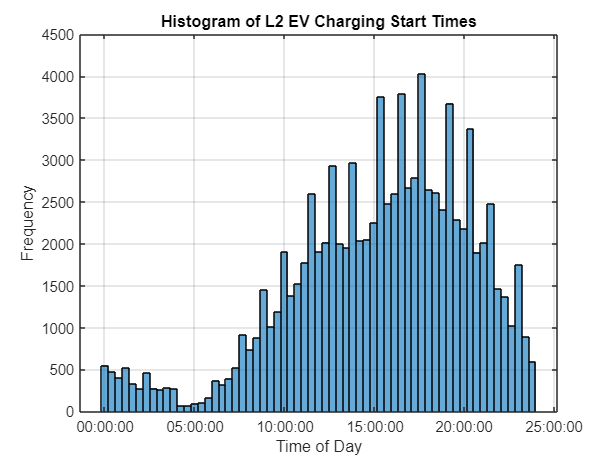

figure;
histogram(L2_start_times_tstamps)
grid on
title("Histogram of L2 EV Charging Start Times")
xlabel("Time of Day")
ylabel("Frequency")

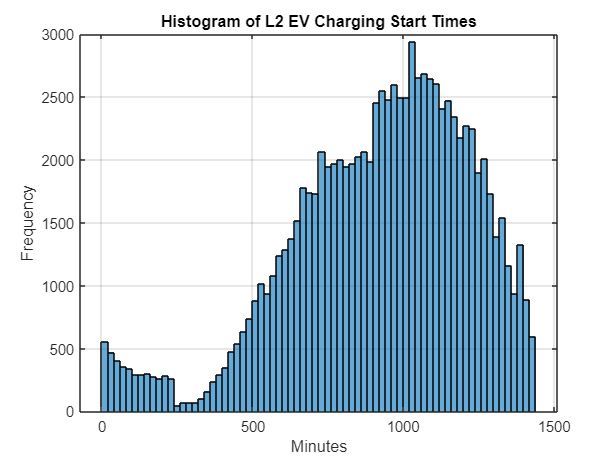

figure;
histogram(L2_start_times_mins)
grid on
title("Histogram of L2 EV Charging Start Times")
xlabel("Minutes")
ylabel("Frequency")

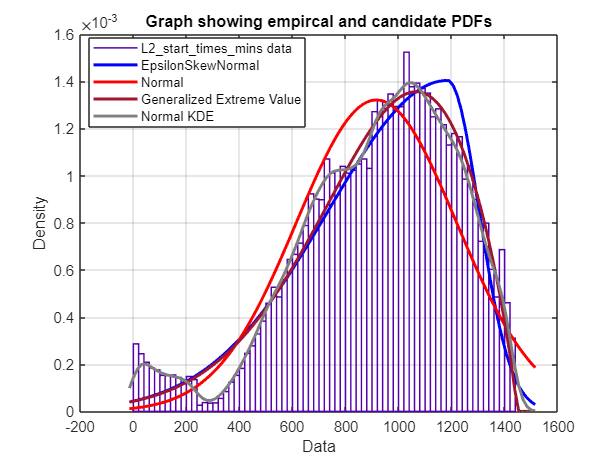

L2_start_times_mins = L2_start_times_mins(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "L2_start_times_mins data"
[CdfF,CdfX] = ecdf(L2_start_times_mins,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(L2_start_times_mins,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'L2_start_times_mins data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "EpsilonSkewNormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('EpsilonSkewNormal',[ 1185.285113895, 284.207698248, 0.5839720286437])
pd1 = fitdist(L2_start_times_mins, 'EpsilonSkewNormal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'EpsilonSkewNormal';

% --- Create fit "Normal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('normal',[ 916.5968890225, 302.0249557112])
pd2 = fitdist(L2_start_times_mins, 'normal');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal';

% --- Create fit "Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('extreme value',[ 1056.718803144, 244.2367402315])
pd3 = fitdist(L2_start_times_mins, 'extreme value');
% This fit does not appear on the plot

% --- Create fit "Generalized Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd4 = ProbDistUnivParam('generalized extreme value',[ -0.5537886012295, 329.3215192628, 851.1268337073])
pd4 = fitdist(L2_start_times_mins, 'generalized extreme value');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.635294 0.0784314 0.184314],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Generalized Extreme Value';

% --- Create fit "Normal KDE"
pd5 = fitdist(L2_start_times_mins,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd5,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.501961 0.501961 0.501961],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
grid on
title('Graph showing empircal and candidate PDFs')

legend("Position",[0.14524,0.72698,0.35179,0.19286])

#### Truncated Starting Times

l2_start_times_trunc = L2_start_times_mins(L2_start_times_mins > 240)

l2_start_times_trunc =          690
        1000
        1170
         920
        1010
        1010
         600
         750
         960
        1100


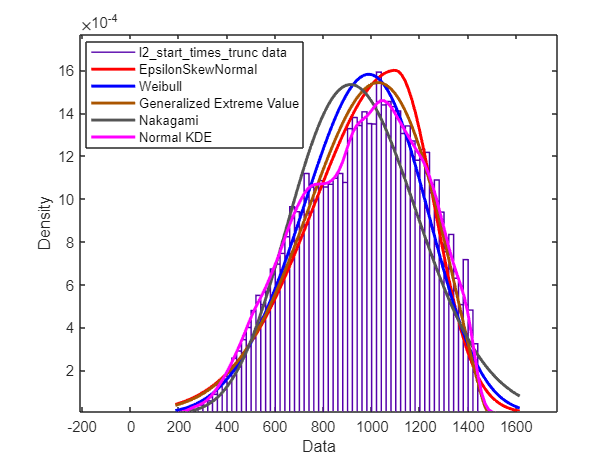

l2_start_times_trunc = l2_start_times_trunc(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "l2_start_times_trunc data"
[CdfF,CdfX] = ecdf(l2_start_times_trunc,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(l2_start_times_trunc,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'l2_start_times_trunc data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "EpsilonSkewNormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('EpsilonSkewNormal',[ 1098.287633767, 249.3964742372, 0.3512617072228])
pd1 = fitdist(l2_start_times_trunc, 'EpsilonSkewNormal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'EpsilonSkewNormal';

% --- Create fit "Weibull"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('weibull',[ 1048.00391362, 4.378365528344])
pd2 = fitdist(l2_start_times_trunc, 'weibull');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Weibull';

% --- Create fit "Generalized Extreme Value"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('generalized extreme value',[ -0.4518578239646, 269.5255256908, 884.6134173835])
pd3 = fitdist(l2_start_times_trunc, 'generalized extreme value');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Generalized Extreme Value';

% --- Create fit "Nakagami"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd4 = ProbDistUnivParam('nakagami',[ 3.49209009481, 972081.6802321])
pd4 = fitdist(l2_start_times_trunc, 'nakagami');
YPlot = pdf(pd4,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.333333 0.333333 0.333333],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Nakagami';

% --- Create fit "Normal KDE"
pd5 = fitdist(l2_start_times_trunc,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd5,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

xlim([-162 1638])
ylim([0.00000 0.00160])
legend("Position",[0.14167,0.68056,0.35179,0.22976])

#### Durations

opts = delimitedTextImportOptions("NumVariables", 1);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = "durations";
opts.VariableTypes = "double";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
l2durationsxformed = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\l2_durations_xformed.csv", opts)

l2durationsxformed = 96497×1 table
    durations
    _________

        20   
        20   
        20   
        20   
        20   
        20   
        20   
        20   
        20   
        40   
        30   
        70   
        30   
        20   
        30   
       150   


clear opts

l2_durs = l2durationsxformed.durations

l2_durs =     20
    20
    20
    20
    20
    20
    20
    20
    20
    40


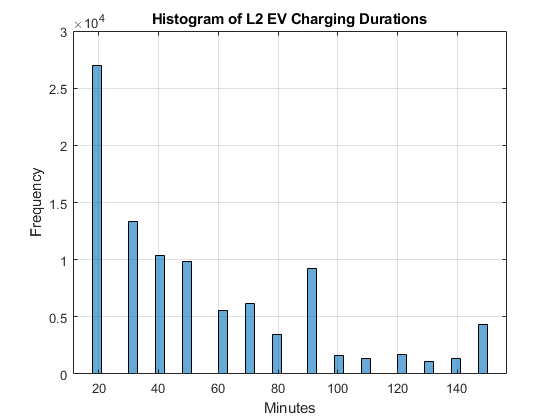

figure;
histogram(l2_durs)
grid on
title("Histogram of L2 EV Charging Durations")
xlabel("Minutes")
ylabel("Frequency")

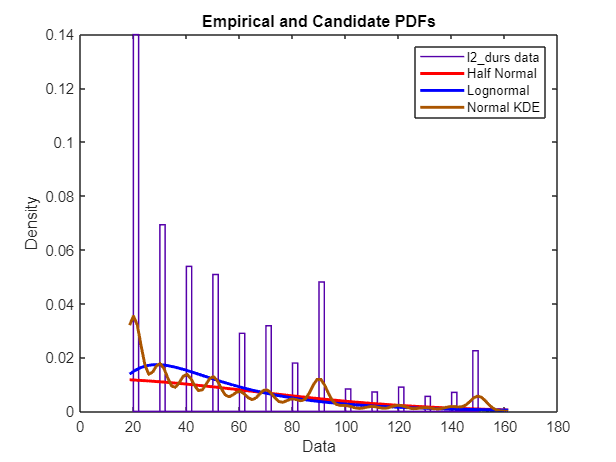

l2_durs = l2_durs(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "l2_durs data"
[CdfF,CdfX] = ecdf(l2_durs,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(l2_durs,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'l2_durs data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "Half Normal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('half normal',[ 20, 50.01501375673])
pd1 = fitdist(l2_durs, 'half normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Half Normal';

% --- Create fit "Lognormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd2 = ProbDistUnivParam('lognormal',[ 3.779587770742, 0.6474049833884])
pd2 = fitdist(l2_durs, 'lognormal');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Lognormal';

% --- Create fit "Normal KDE"
pd3 = fitdist(l2_durs,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

#### Truncating Duration

l2_dur_trunc = l2_durs(l2_durs > 30)

l2_dur_trunc =     40
    70
   150
    60
    50
   150
    50
    90
    50
   130


l2_dur_trunc =     40
    70
    60
    50
    50
    90
    50
   130
    90
   120


l1_durs =    110
    30
    80
    40
    40
    50
    40
    30
    60
   120


l2_dur_trunc = l2_dur_trunc(l2_dur_trunc < 140)

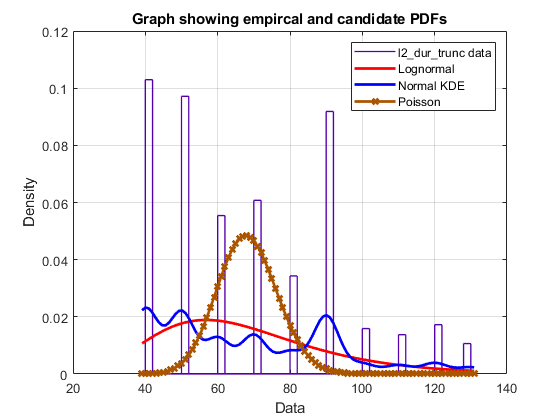

l2_dur_trunc = l2_dur_trunc(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "l2_dur_trunc data"
[CdfF,CdfX] = ecdf(l2_dur_trunc,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(l2_dur_trunc,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'l2_dur_trunc data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));


% --- Create fit "Lognormal"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('lognormal',[ 4.161673100323, 0.3496428981824])
pd1 = fitdist(l2_dur_trunc, 'lognormal');
XGrid = XContinuous;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Lognormal';

% --- Create fit "Normal KDE"
pd2 = fitdist(l2_dur_trunc,'kernel','kernel','normal','support','unbounded');
XGrid = XContinuous;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Normal KDE';

% --- Create fit "Poisson"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd3 = ProbDistUnivParam('poisson',[ 68.24445942196])
pd3 = fitdist(l2_dur_trunc, 'poisson');
XGrid = XDiscrete;
YPlot = pdf(pd3,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.666667 0.333333 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','x', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'Poisson';

% Adjust figure
box on;
grid on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
title('Graph showing empircal and candidate PDFs')